clc
clear
addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\mcx'))
addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\iso2mesh'))

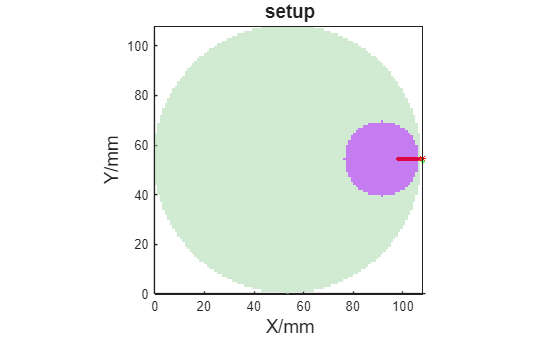

%% 2D CSF simulation main simulation
save_flag = 0; % 0 is not saving any picture
clear cfg_csf;

% % % % general setting
cfg_csf.nphoton = 1e8;
cfg_csf.gpuid = '11'; % use two GPUs
cfg_csf.workload = [10,10];  % evenly use the two GPUs
cfg_csf.autopilot = 1;
cfg_csf.maxdetphoton = cfg_csf.nphoton;
brain_size = [108 108]; % number of brain voxels
cfg_csf.vol = permute(uint8(zeros(brain_size)), [3, 1, 2]); % from 2d to 3d
cfg_csf.tstart = 0;
cfg_csf.tend = 5e-9;
cfg_csf.tstep = 5e-9;
cfg_csf.debuglevel = 'P'; % show progress bar
cfg_csf.unitinmm = 1;
cfg_csf.issrcfrom0 = 1;  % 1-first voxel is [0 0 0], [0]- first voxel is [1 1 1]
% % % % general setting end

% % % % build indices for the voxels, use voxel center
center_pos = ceil((brain_size-1)/2);
[grid_z,grid_y] = ndgrid(linspace(brain_size(1)-1,0,brain_size(1)'),linspace(0,brain_size(2)-1,brain_size(2)'));

dmua = 0.02; % difference in mua because of tumour

% % % % set brain segmentation
% % % % type [0 air, 1 GM, 2 CSF]
cfg_csf.prop = [0 0 1 1;
    0.033 1 0 1.33;
    0.0420 0.01 0 1.33
    0.033+dmua 1 0 1.33];

D_from_center = sqrt((grid_z-center_pos(1)).^2+(grid_y-center_pos(2)).^2);
csf_radius = [49 49+3];

for i = 1:brain_size(1)
    for j = 1:brain_size(2)
        switch true
            case D_from_center(i,j)>=csf_radius(1)&&D_from_center(i,j)<csf_radius(2)
                cfg_csf.vol(1, i, j) = 1;
            case D_from_center(i,j)<=ceil(brain_size(1)/2)
                cfg_csf.vol(1, i, j) = 1;
        end
    end
end

% % % % source set---------------------------------------
source_radius = 54; source_angle_rad =  + 0.01;
src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
meas_radius = 54; meas_angle_rad =  - 0.01 ; % pi/2 -0.5 pi/2+0.01
mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
cfg_csf.srcpos = [0, center_pos(1)+src_pos(1), center_pos(2)+src_pos(2)];
cfg_csf.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)
cfg_csf.srctype = 'pencil';
% % % %  source set end-----------------------------------

% % % % det set
cfg_csf.detpos = [0, center_pos(1)+mea_pos(1), center_pos(2)+mea_pos(2), 1];
% % % %  det set end


% % % % set tumour
tuc_pos = [38 0];
tuC = [center_pos(1)-tuc_pos(1) center_pos(2)+tuc_pos(2)];
tuR = 15;
D2C = sqrt((grid_z-tuC(1)).^2+(grid_y-tuC(2)).^2);
for i = 1:brain_size(1)
    for j = 1:brain_size(2)
        if D2C(i,j)<=tuR
            cfg_csf.vol(1, i, j) = 3;
        end
    end
end

% % % % set tumour end

% % % % show the setup
figure,mcxpreview(cfg_csf); title('setup',FontSize=14); view([90,0]);
ylabel('X/mm',FontSize=14)
zlabel('Y/mm',FontSize=14)

## run the simulation of distance0

cfg_csf.outputtype = 'flux';
% cfg_csf.outputtype = 'jacobian';
rng('default')


source_angle = linspace(-pi/2,0,5)';
det_angle = linspace(-pi/2,pi/2,9)';
weight = zeros(size(det_angle,1)*size(source_angle,1),1);
weight_p = zeros(size(det_angle,1)*size(source_angle,1),1);

for i = 1:size(det_angle,1)*size(source_angle,1)

    [im,is] = ind2sub([size(det_angle,1),size(source_angle,1)],i);

    source_radius = 54; source_angle_rad =  source_angle(is);
    meas_radius = 54; meas_angle_rad = det_angle(im) ;

    src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
    mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
    cfg_csf.srcpos = [0, center_pos(1)+src_pos(1), center_pos(2)+src_pos(2)];
    cfg_csf.detpos = [0, center_pos(1)+mea_pos(1), center_pos(2)+mea_pos(2), 1];
    cfg_csf.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)


    [~, detp_csf, ~, ~] = mcxlab(cfg_csf);
    weight(i) = sum(mcxdetweight(detp_csf,cfg_csf.prop,cfg_csf.unitinmm));

    prop_p = cfg_csf.prop;
    prop_p(4,1) = prop_p(4,1) + dmua;
    weight_p(i) = sum(mcxdetweight(detp_csf,prop_p,cfg_csf.unitinmm));
end

Launching MCXLAB - Monte Carlo eXtreme for MATLAB & GNU Octave ...
Running simulations for configuration #1 ...
mcx.nphoton=1e+08;
mcx.gpuid='11';
mcx.workload=<<2>>;
mcx.autopilot=1;
mcx.maxdetphoton=1e+08;
mcx.dim=[1 108 108];
mcx.mediabyte=1;
mcx.tstart=0;
mcx.tend=5e-09;
mcx.tstep=5e-09;
mcx.debuglevel=4;
mcx.unitinmm=1;
mcx.issrcfrom0=1;
mcx.medianum=4;
mcx.srcpos=[0 54 0 1];
mcx.srcdir=[0 -6.12323e-17 1 0];
mcx.srctype='pencil';
mcx.detnum=1;
mcx.outputtype='flux';
###############################################################################
#                      Monte Carlo eXtreme (MCX) -- CUDA                      #
#          Copyright (c) 2009-2025 Qianqian Fang <q.fang at neu.edu>          #
#                https://mcx.space/  &  https://neurojson.io                  #
#                                                                             #
# Computational Optics & Translational Imaging (COTI) Lab- http://fanglab.org #
#   Department of Bioengineering, Northeaste

## data post-process and calculate FI

% Convert amplitude to counts per second (cps)
% input_power_density = 3e-3; % maximum safty threshold 3mw/mm^2
addpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\tomography241015\NIRfast_code_241118\nirfast_fisher_numerical_311224')
input_power_v = [1e-4 5e-4 1e-3 3e-3]; % W/mm^2
% input_power_v = [1e-7 1e-6 1e-5 1e-4]; % W/mm^2
% input_power_v = [1e-10];
amplitude = weight./cfg_csf.nphoton;
amplitude_p = weight_p./cfg_csf.nphoton;

Fisher_result_batch_csf = zeros(length(amplitude),length(input_power_v));
PC_batch_csf = zeros(length(amplitude),length(input_power_v));
dIdmua_batch_csf = zeros(length(amplitude),length(input_power_v));
ind_result = 1;

for input_power_density =  input_power_v

    h = 6.626e-34; % Planck constant in Js
    lambda = 800e-9; % wavelength in m
    sp_eng = h.*wavelen2freq(lambda); % single photon energy
    exposure_time = 0.1;
    bandwidth = 1/exposure_time/2;
    photon_counts = round(amplitude.*input_power_density/sp_eng*exposure_time*1); % exposure time 0.1s and area 1mm^2
    photon_counts_p = round(amplitude_p.*input_power_density/sp_eng*exposure_time*1); % exposure time 0.1s and area 1mm^2

    PC_batch_csf(:,ind_result) = photon_counts;

    pc_threshold = 1e8*exposure_time; % the threshold of SPAD max cps
    dI_dmua = (amplitude_p.*input_power_density/sp_eng*exposure_time*1-amplitude.*input_power_density/sp_eng*exposure_time*1)./dmua; % calculate how the intensity change with tumour radius
    dI_dmua = dI_dmua.*(abs(dI_dmua)>1);

    dIdmua_batch_csf(:,ind_result) = dI_dmua;

    % % % % distinguish according to threshold
    Poisson_ind = photon_counts<=pc_threshold;
    Gaussian_ind = photon_counts>pc_threshold;

    % % % % gaussian noise level
    nep = 1e-13; % W/sqrt(Hz)
    Gaussian_std = nep*sqrt(bandwidth)/sp_eng*exposure_time;
    % std of CPS, exposure time 0.1s

    Fisher_result = dI_dmua.^2.*1./photon_counts.*Poisson_ind; % Poisson noise
    Fisher_result(isnan(Fisher_result)) = 0;

    % % % % Gaussian noise+poisson noise
    % for i = 1:length(Fisher_result(:))
    parfor (i = 1:length(Fisher_result(:)),4)
        if Gaussian_ind(i) == 1
            Fisher_result(i) = calculate_Gau_Pos_FI(Gaussian_std,photon_counts(i),dI_dmua(i));
        end
    end

    Fisher_result_batch_csf(:,ind_result) = Fisher_result;
    ind_result = ind_result+1;
end

## show result

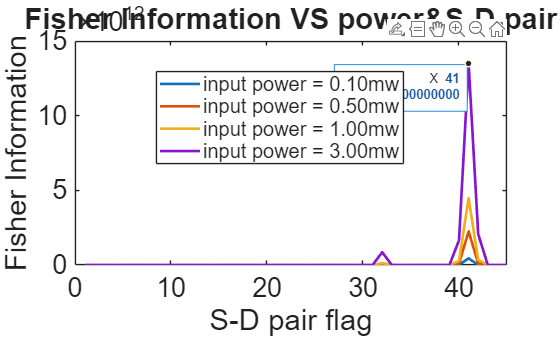

figure;
for i = 1:size(Fisher_result_batch_csf,2)
    plot((Fisher_result_batch_csf(:,i)),LineWidth=2);hold on
end
xlabel("S-D pair flag")
ylabel('Fisher Information')
ax = gca; ax.FontSize = 20;
title('Fisher Information VS power&S-D pair')

legend_str = '';
for i = 1:length(input_power_v)
    legend_str{end+1} = sprintf('input power = %0.2fmw',input_power_v(i)*1e3);
end

legend(legend_str,'Fontsize',15)

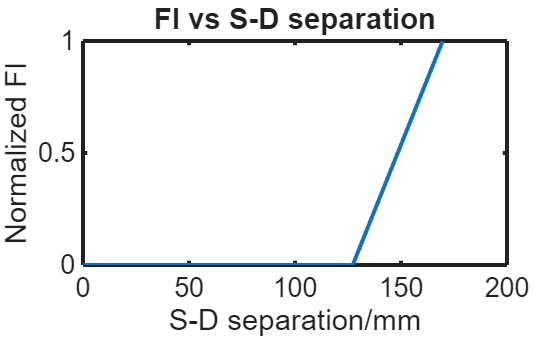


figure; % show how Fisher Information change with distance
index_dist = sub2ind([size(det_angle,1),size(source_angle,1)],5:9,5:-1:1);
plot(linspace(0,54*pi,5), ...
    (Fisher_result_batch_csf(flip(index_dist),4)./max(Fisher_result_batch_csf(index_dist,4))),LineWidth=3);hold on
xlabel('S-D separation/mm')
ylabel('Normalized FI')
title('FI vs S-D separation')
% axis square
ax = gca; ax.FontSize = 20;ax.LineWidth = 3;        

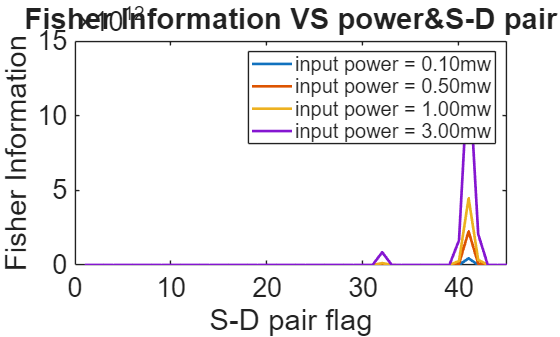


figure;
for i = 1:size(Fisher_result_batch_csf,2)
    plot((Fisher_result_batch_csf(:,i)),LineWidth=2);hold on
end
xlabel("S-D pair flag")
ylabel('Fisher Information')
ax = gca; ax.FontSize = 20;
title('Fisher Information VS power&S-D pair')

legend_str = '';
for i = 1:length(input_power_v)
    legend_str{end+1} = sprintf('input power = %0.2fmw',input_power_v(i)*1e3);
end

legend(legend_str,'Fontsize',15)

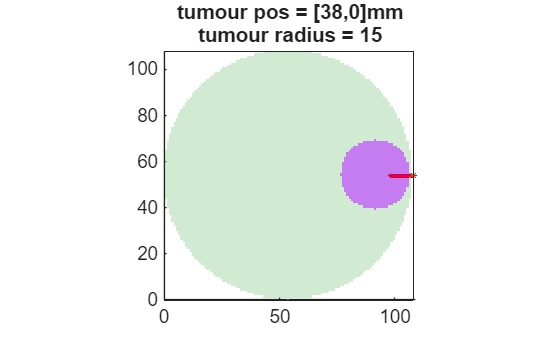

target_sd_pair = 41;

[im,is] = ind2sub([size(det_angle,1),size(source_angle,1)],target_sd_pair);

source_radius = 54; source_angle_rad =  source_angle(is);
meas_radius = 54; meas_angle_rad =  det_angle(im) ;
src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
cfg_csf.srcpos = [0, center_pos(1)+src_pos(1), center_pos(2)+src_pos(2)];
cfg_csf.detpos = [0, center_pos(1)+mea_pos(1), center_pos(2)+mea_pos(2), 1];
cfg_csf.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)

figure;mcxpreview(cfg_csf); title(sprintf('tumour pos = [%d,%d]mm\ntumour radius = %d',tuc_pos(1),tuc_pos(2) ...
    ,tuR)); view([90,0]);
colormap('parula')
ax = gca; ax.FontSize = 14;

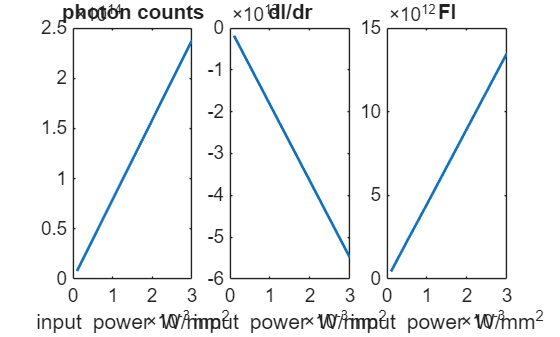


figure;
subplot(1,3,1)
plot(input_power_v,(PC_batch_csf(target_sd_pair,:)),LineWidth=2);
title('photon counts')
xlabel('input power W/mm^2')
ax = gca; ax.FontSize = 14;

subplot(1,3,2)
plot(input_power_v,dIdmua_batch_csf(target_sd_pair,:),LineWidth=2);
title('dI/dr')
xlabel('input power W/mm^2')
ax = gca; ax.FontSize = 14;

subplot(1,3,3)
plot(input_power_v,Fisher_result_batch_csf(target_sd_pair,:),LineWidth=2);
title('FI')
xlabel('input power W/mm^2')
ax = gca; ax.FontSize = 14;